%阴极钛箔
t_ti_1=[0	72	122	174	221	269	320	368	416	466	485	559	610	654	701	747	793	827	880	930	976];
t_ti_2=[0	53	87	131	176	222	268	312	356	401	450	495	544	590	641	684	731	779	824	874	921];
t_ti_3=[0	56	112	169	224	274	323	369	412	456	500	544	589	634	674	730	777	826	875	927	971];
u_ti_1=[2.6	3.1	3.4	3.9	4.3	4.7	5.1	5.5	5.9	6.3	6.7	7.1	7.5	8	8.3	8.7	9.2	9.6	10	10.3	10.9];
u_ti_2=[2.3	2.7	2.9	3.3	3.6	4	4.4	4.7	5.1	5.5	5.9	6.3	6.7	7.1	7.5	7.9	8.3	8.7	9.1	9.6	10.1];
u_ti_3=[2.2	2.7	3.1	3.6	4	4.4	4.8	5.2	5.6	5.9	6.3	6.7	7.1	7.5	7.8	8.3	8.7	9.2	9.6	10.1	10.5];
t_ti=(t_ti_1+t_ti_2+t_ti_3)/3

t_ti =          0   60.3333  107.0000  158.0000  207.0000  255.0000  303.6667  349.6667  394.6667  441.0000  478.3333  532.6667  581.0000  626.0000  672.0000  720.3333  767.0000  810.6667  859.6667  910.3333  956.0000


u_ti=(u_ti_1+u_ti_2+u_ti_3)/3

u_ti =     2.3667    2.8333    3.1333    3.6000    3.9667    4.3667    4.7667    5.1333    5.5333    5.9000    6.3000    6.7000    7.1000    7.5333    7.8667    8.3000    8.7333    9.1667    9.5667   10.0000   10.5000


y=0:50:1000

y =            0          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000


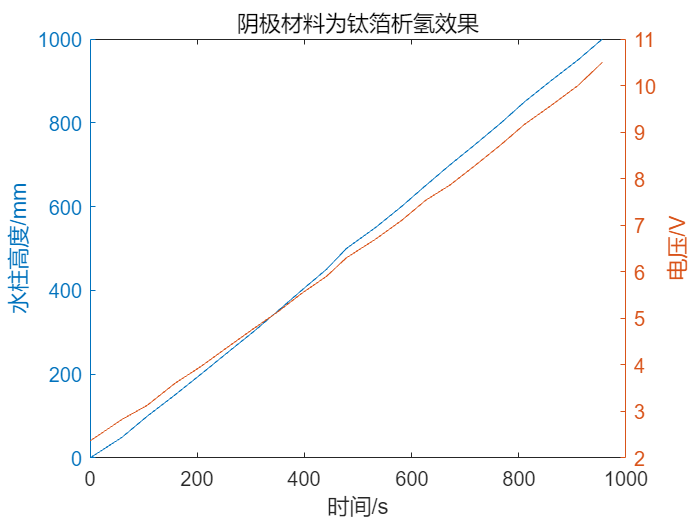


%折线图
figure;
yyaxis left;
plot(t_ti,y);
ylabel('水柱高度/mm');
yyaxis right;
plot(t_ti,u_ti);
xlabel('时间/s');
ylabel('电压/V');
title('阴极材料为钛箔析氢效果');

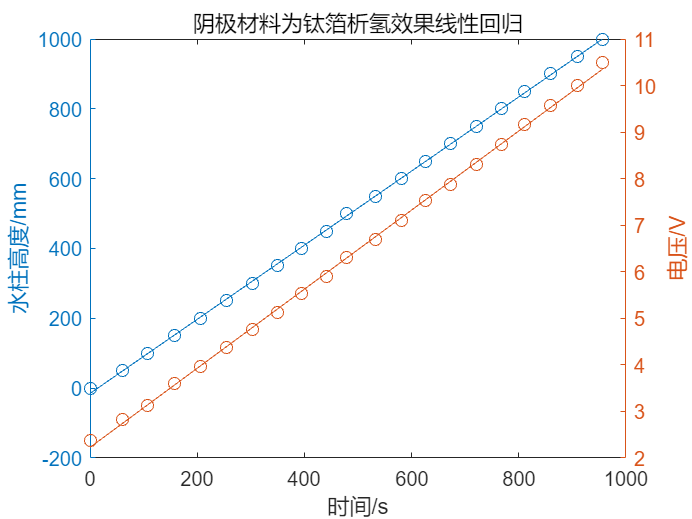


%线性拟合
figure;
yyaxis left;
pt_ti=polyfit(t_ti,y,1);
ft_ti=polyval(pt_ti,t_ti);
plot(t_ti,y,'o',t_ti,ft_ti,'-');
ylabel('水柱高度/mm');
yyaxis right;
pu_ti=polyfit(t_ti,u_ti,1);
fu_ti=polyval(pu_ti,t_ti);
plot(t_ti,u_ti,'o',t_ti,fu_ti,'-');
xlabel('时间/s');
ylabel('电压/V');
title('阴极材料为钛箔析氢效果线性回归');